## Numerical Integration

In this livescript, you will learn how to

- Apply the Trapezoidal rule and Simpsons's rule to approximate integrals.

- Apply Gaussian quadrature to approximate integrals

### Numerical Integration

The main idea behind numerical integration (or quadrature) is to approximate a complicated function at some set of points using a Lagrange polynomial, which we can then easily integrate.

### Trapezoidal Rule

The easiest method of approximating a function is to assume that it varies linearly between the end points.


$$f_{1}(x)\approx f(x_{0})\frac{x-x_{1}}{x_{1}-x_{0}}+f(x_{1})\frac{x-x_{0}}{x_{0}-x_{1}}$$


Which we may then integrate to find


$$\int^{x_{1}}_{x_{0}}{f(x)dx}\approx\int^{1}_{0}{f_{1}(x)dx}=\frac{\Delta}{2}[f(x_{0})+f(x_{1})]$$


where $\Delta=x_{1}-x_{0}$. 

For example, with $f(x)=\exp(x)$

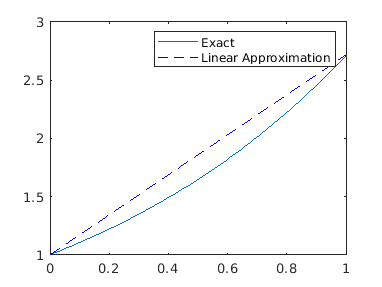

x = linspace(0,1,100);
f = @(x)exp(x);
plot(x,f(x))
hold on 
plot([0 1],[f(0) f(1)],'b--')
legend('Exact','Linear Approximation')
hold off

However, we do see that the linear approximation does overestimate the function, and thus so will the integral.

And in fact, the error can be found by integrating the error in the Lagrange polynomial from last week


$$E(t)=\frac{(t-x_{0})(t-x_{1})}{2}f''(\xi)$$


(a)        Show that the error in the integral is given by


$$\frac{\Delta^{3}}{12}f''(\xi)$$


             for some $\xi$ in $[x_{0},x_{1}]$.

(b)        Using your answer to part (a) obtain a maximal bound for the error in applying the trapezoidal rule to 


$$\int^{1}_{0}{\exp{(x)}dx}$$


Implementing this in MATLAB, we have

f = @(x) exp(x);
b = 1;
a = 0;

delta = (b-a);

I = (delta/2)*(f(a)+f(b))

I = 1.8591

The error is therefore given by

Error = abs((f(1)-f(0))-I)

Error = 0.1409

(c)        Run this command and compare this with your answer in part (b).

We see that the Trapezoidal rule provides a poor approximation to the integral. However, a way of improving the accuracy of the integral is to approximate the function by dividing it into smaller intervals and applying a linear approximation to each interval.

For our example, with two intervals, we can see that the large error in the linear Lagrange polynomial at the centre is avoided.

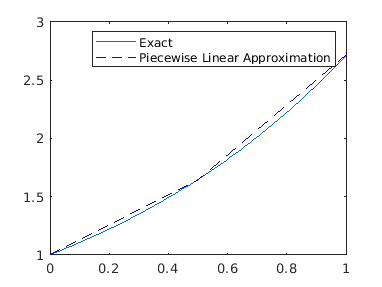

x = linspace(0,1,100);
f = @(x)exp(x);
plot(x,f(x))
hold on 
plot([0 0.5 1],[f(0) f(0.5) f(1)],'b--')
legend('Exact','Piecewise Linear Approximation')
hold off

So, decomposing the integral into the two integrals over these smaller sub-intervals, we have


$$\int^{1}_{0}{\exp(x)dx}=\int^{1}_{0.5}{\exp(x)dx}+\int^{0.5}_{0}{\exp(x)dx}$$


And applying the Trapezoidal rule


$$\int^{1}_{0}{\exp(x)dx}\approx\frac{\Delta}{2}[f(x_{0})+f(x_{0.5})]+\frac{\Delta}{2}[f(x_{0.5})+f(x_{1})]$$


For an arbitrary function $f$, we can extend this argument to $N$ arbitrary intervals to give


$$\int^{x_{N}}_{x_{0}}{f(x)dx}=\sum^{N-1}_{i=0}\int^{x_{i+1}}_{x_{i}}{f(x)dx}$$


(d)        Assume that each sub-interval is equally spaced. Show that by applying the trapezoidal rule to each sub-interval gives


$$\int^{1}_{0}{f(x)dx}\approx \frac{\Delta}{2}\Big(f(x_{0})+2\sum^{N-1}_{i=1}{f(x_{i})+f(x_{N})\Big)$$


Coding this in MATLAB gives the following piece of code.

a = 0;
b = 1;
N = 2;
f = @(x) exp(x)

f = function_handle with value:
    @(x)exp(x)



delta = (b-a)/N;

xi = linspace(a,b,N+1)

xi =          0    0.5000    1.0000


fi = f(xi);

I = (delta/2)*(fi(1)+2*sum(fi(2:end-1))+fi(end))

I = 1.7539

(d)        Run this piece of code for $N=2,4,8,16,32$ intervals.

As for the error them, since we have $N$ intervals, the error in the integral is 


$$\sum^{N}_{i=1}\frac{\Delta^{3}}{12}f''(\xi_{i})=\frac{b-a}{12}\Delta^{2}f''(\mu)$$


for some $\mu\in[a,b]$.

To verify this, the following code fragments computes the error in the integral for the segments in part (d).

a = 0;
b = 1;
f = @(x) exp(x)

f = function_handle with value:
    @(x)exp(x)


error = zeros(1,10);

for k = 1:10
    N = 2^k;
        
    delta = (b-a)/N;
    
    xi = linspace(a,b,N+1);
    fi = f(xi);
    
    I = (delta/2)*(fi(1)+2*sum(fi(2:end-1))+fi(end))
    error(k) = I;
end

I = 1.7539

I = 1.7272

I = 1.7205

I = 1.7188

I = 1.7184

I = 1.7183

I = 1.7183

I = 1.7183

I = 1.7183

I = 1.7183


g = fitlm(log10(2.^[1:10]),log10(abs((f(1)-f(0))-error)))

'fitlm' requires Statistics and Machine Learning Toolbox.

plot(g)

(e)        Run the code and see if the fit matches the predicted results.

### Simpson's Rule

Another way we could refine the integral is to increase the order of the interpolating polynomial as well.

If we add an interior node in the middle, then our Lagrange polynomial is 


$$f_{2}(x)=f(x_{0})\frac{(x-x_{1})(x-x_{2})}{(x_{0}-x_{1})(x_{0}-x_{2})}+
f(x_{1})\frac{(x-x_{0})(x-x_{2})}{(x_{1}-x_{0})(x_{1}-x_{2})}+
f(x_{2})\frac{(x-x_{0})(x-x_{1})}{(x_{2}-x_{0})(x_{2}-x_{1})}$$


Integrating over the interval $x_{0}\leq x \leq x_{2}$ gives


$$\int^{x_{2}}_{x_{0}}{f_{2}(x)dx}=\frac{\Delta}{3}[f(x_{0})+4f(x_{1})+f(x_{2})]$$


Furthermore, using the Taylor series expansion of $f$, it is possible to show that the error in Simpson's rule is given by


$$E_{\text{int}}=\Big|\frac{\Delta^{5}}{90}f^{(4)}(\xi)\Big|$$


Turning back to the example


$$f(x)=\exp(x)$$


If we plot the quadratic interpolating polynomial at the nodes $x=0,0.5,1$, we find

x = linspace(0,1,100);
f = @(x)exp(x);
a = polyfit([0 0.5 1],exp([0 0.5 1]),2);
plot(x,f(x))
hold on 
plot(x,polyval(a,x),'b--')
legend('Exact','Quadratic Approximation')
hold off

Which is much more accurate than the linear interpolating polynomial.

Hence, we expect the integral to be more accurate as well.

f = @(x) exp(x);
b = 1;
a = 0;
c = (b-a)/2;

delta = (b-a)/2;

I = (delta/3)*(f(a)+4*f(c)+f(b))

The error is therefore given by

Error = abs((f(1)-f(0))-I)

which is much smaller than with the trapezoidal rule with a single interval.

Again, we can also refine the integral by using smaller subintervals. For two sub-intervals

x = linspace(0,1,100);
f = @(x)exp(x);
a1 = polyfit([0 0.25 0.5],exp([0 0.25 0.5]),2);
a2 = polyfit([0.5 0.75 1],exp([0.5 0.75 1]),2);
plot(x,f(x))
hold on 
plot(x,[polyval(a1,x(1:50)),polyval(a2,x(51:100))],'b--')
legend('Exact','Quadratic Approximation')
hold off

Applying Simpson's rule gives


$$\int^{x_{N}}_{x_{0}}{f(x)dx}\approx\frac{\Delta}{3}\Big(f(x_{0})+4\sum^{N-1}_{i=1,i\text{odd}}{f(x_{i})}+2\sum^{N-2}_{i=1,i\text{even}}{f(x_{i})}+f(x_{N})\Big)$$


And the error


$$E_{\text{int}}=\frac{\Delta^{5}}{90}\sum^{N/2}_{j=1}{|f^{(4)}(\xi_{j})|=\Big|\frac{(b-a)}{180}\Delta^{4}f^{(4)}(\mu)\Big|$$


In MATLAB a piece of code that computes this is

a = 0;
b = 1;
N = 2;
f = @(x) exp(x)

delta = (b-a)/(2*N);

xi = linspace(a,b,N+1);
c = (xi(2:end)+xi(1:end-1))/2;

fout = f(xi);
fint = f(c);

I = (delta/3)*(fout(1)+2*sum(fout(2:end-1))+4*sum(fint)+fout(end))

(f)         Re-run the code with $N=2,4,8,16,32,64,128,256,512,1024$ intervals.

(g)        Perform a numerical experiment with the points in part (f).

### Gaussian Quadrature

As we saw last week, using equally spaced nodes to interpolate a polynomial can lead to large oscillations near the end points. For example, approximating the *Witch of Agnesi* with an 8th order interpolating polynomial

x = linspace(-1,1,1000);
f = @(x) 1./(1+25*x.^2);
x_even = linspace(-1,1,9);

f_even_interp = polyval(polyfit(x_even,f(x_even),8),x)

plot(x,f(x),x,f_even_interp)

Which wouldn't provide a very good approximation to integrate.

Therefore, we seek a set of points $\{x\}$ such that the quadrature of order $N$ integrates a polynomial $2N-1$ exactly. In lectures, you would have seen that this set of points $\{x\}$ corresponds with the the roots of the Legendre polynomial of order $N$.

The only problem here is that finding the roots of associated Legendre polynomial can be tricky. In MATLAB the problem isn't too severe as there is the $\texttt{legendreP(n,x)$ function, which we can then solve to obtain the quadrature points. As for the quadrature weights, analytical expressions do exist, however are a bit complicated and won't be given here. So, we've provided the function $\texttt{gauss\_legendre\_points(k)}$ to give the weights and points for the k-point Gauss-Legendre quadrature rule

[w,x_GL] = gauss_legendre_points(4)

So, using the Gauss-Legendre points to approximate the *Witch of Agnesi* we find 

[w,x_GL] = gauss_legendre_points(9);

f_GL_interp = polyval(polyfit(x_GL,f(x_GL),8),x)

plot(x,f(x),x,f_GL_interp)

which is a much better approximation.

To illustrate how one would use Gauss-Legendre quadrature to evaluate and integral, consider 


$$I=\int^{b}_{a}{\exp{(x)}dx}$$


where $b=1$ and $a=0$.

Notice that the interval is $0\leq x\leq1$ whereas the Gauss-Legendre quadrature rules only apply for the standard interval $-1\leq \xi\leq 1$.

**Step 1.** We need to first relate the global coordinates $x$ to the local coordinates $\xi$, which we can do using the mapping


$$x(\xi)=\frac{1}{2}(1-\xi)a+\frac{1}{2}(1+\xi)b$$


**Step 2.** To convert the integral from global coordinates to local coordinates, determine the Jacobian of the mapping using


$$\frac{dx}{d\xi}=\frac{b-a}{2}$$


Hence the integral is given by


$$I=\int^{1}_{-1}{\exp{\{x(\xi)\}}\frac{b-a}{2}d\xi}$$


**Step 3.** Use the Gauss-Legendre rules to approximate $I$


$$I=\sum^{k}_{i=0}{w_{i}\exp{\{x(\xi_{i})\}}\frac{b-a}{2}$$


A piece of code that uses the $\texttt{sum}$ function to compute $I$ is given below

a = 0;
b = 1;

N = 10;
[w,xi] = gauss_legendre_points(N);
x = 0.5.*(1-xi).*a+0.5.*(1+xi).*b;
f = exp(x);

I = sum(w.*f)*(b-a)/2

(h)    Run this piece of code and see if how well it matches the exact value.